## Smith Trigger

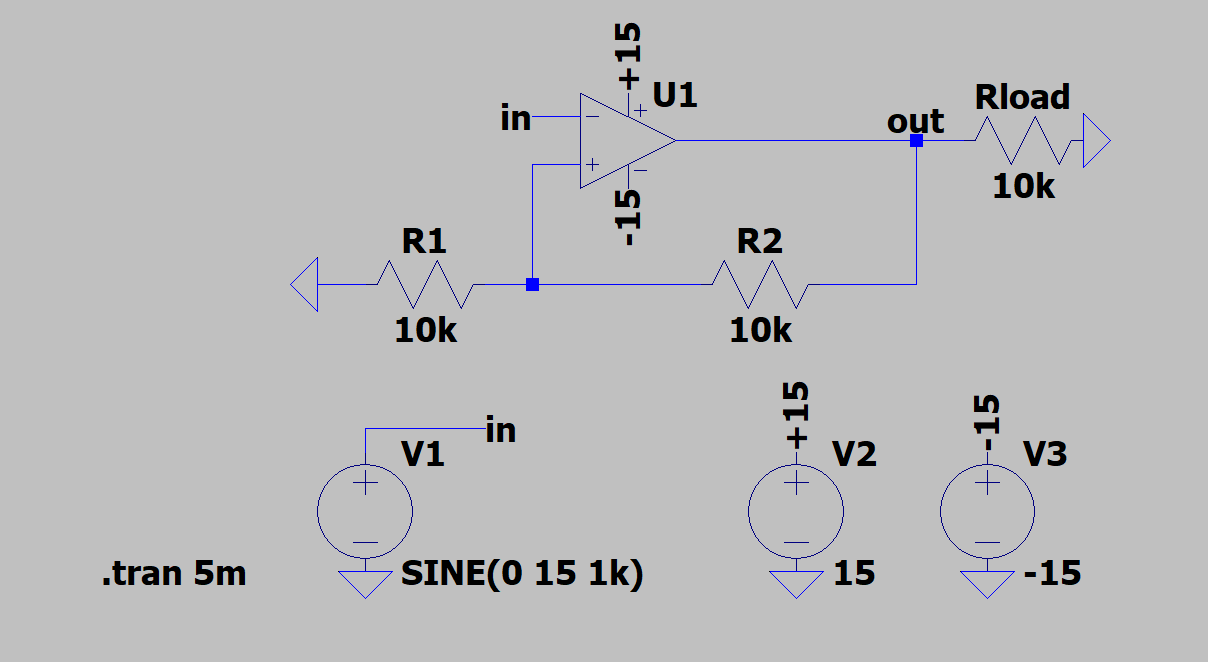 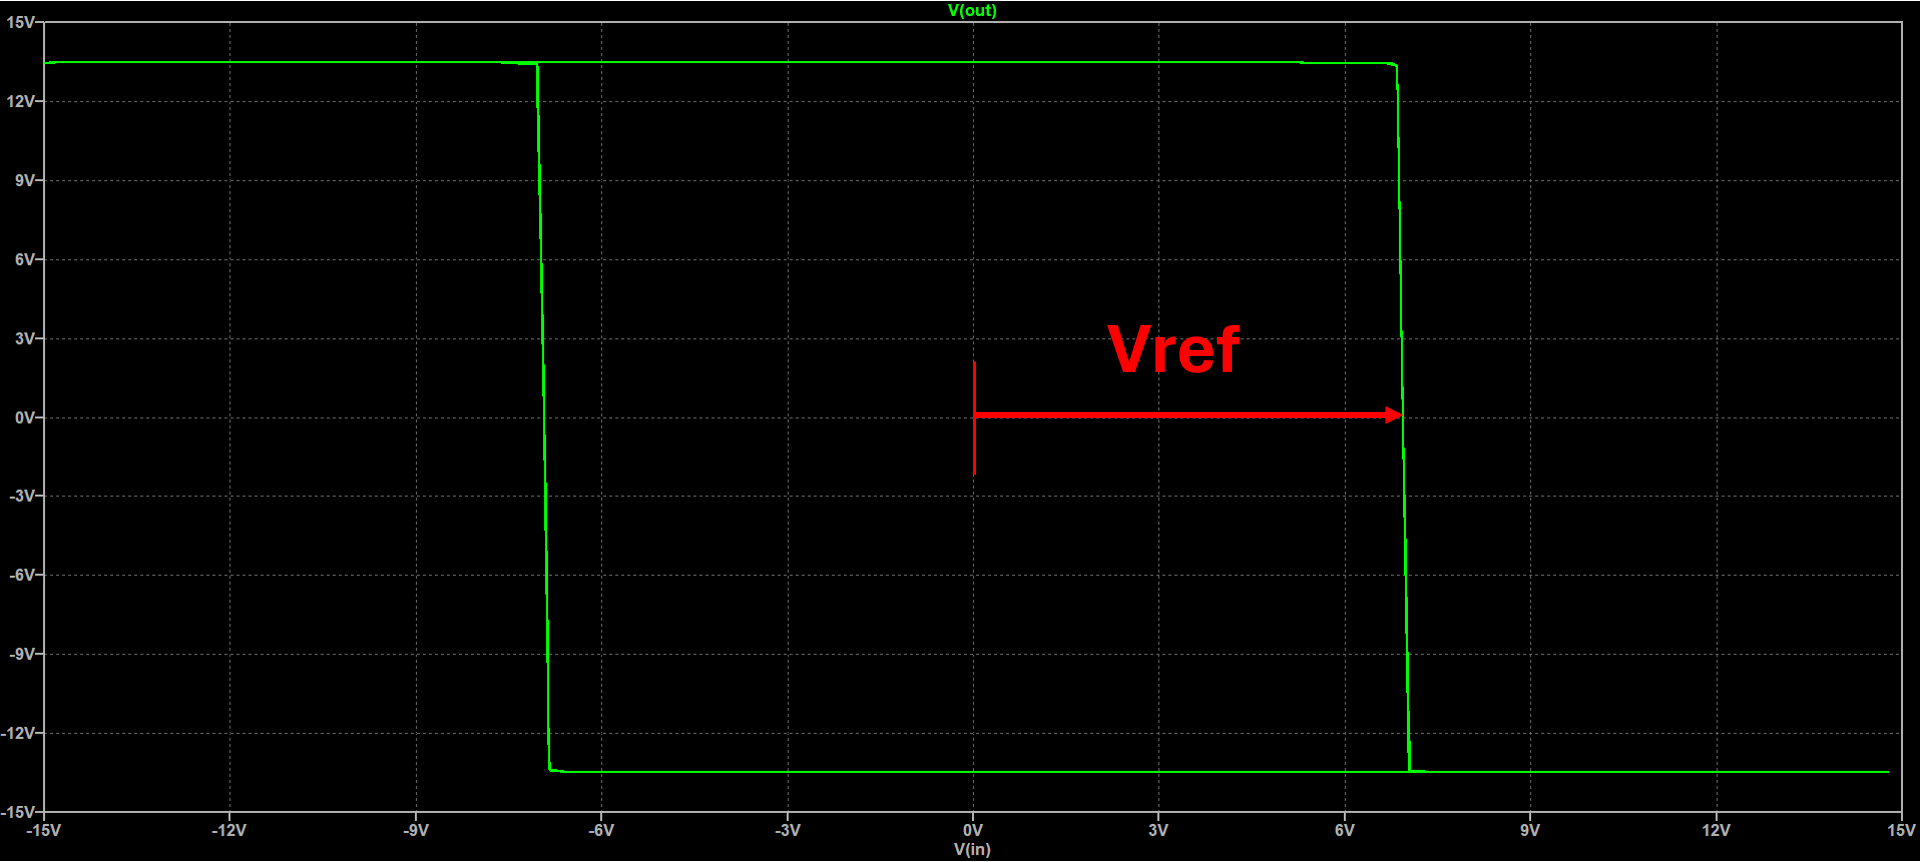

f = 10 * 1e3;  %Hz     % USUALLY GIVEN
V_ref = 7.5;   %V      % USUALLY GIVEN/TO BE DECIDED
R1 = 10 * 1e3; %ohm    % TO BE DECIDED

Vcc = 15; %V

beta = V_ref/Vcc;
R2 = R1/beta-R1;

disp("Trigger Smith")

Trigger Smith


disp("R1 = "+ R1)

R1 = 10000


disp("R2 = "+ R2)

R2 = 10000


## Astable Multivibrator (square wave generator + triangular wave)

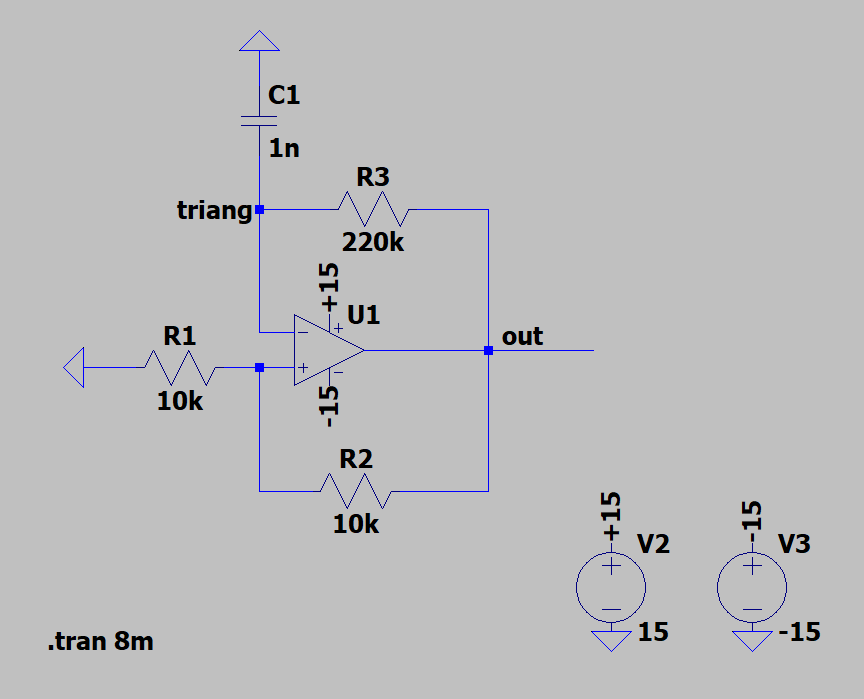

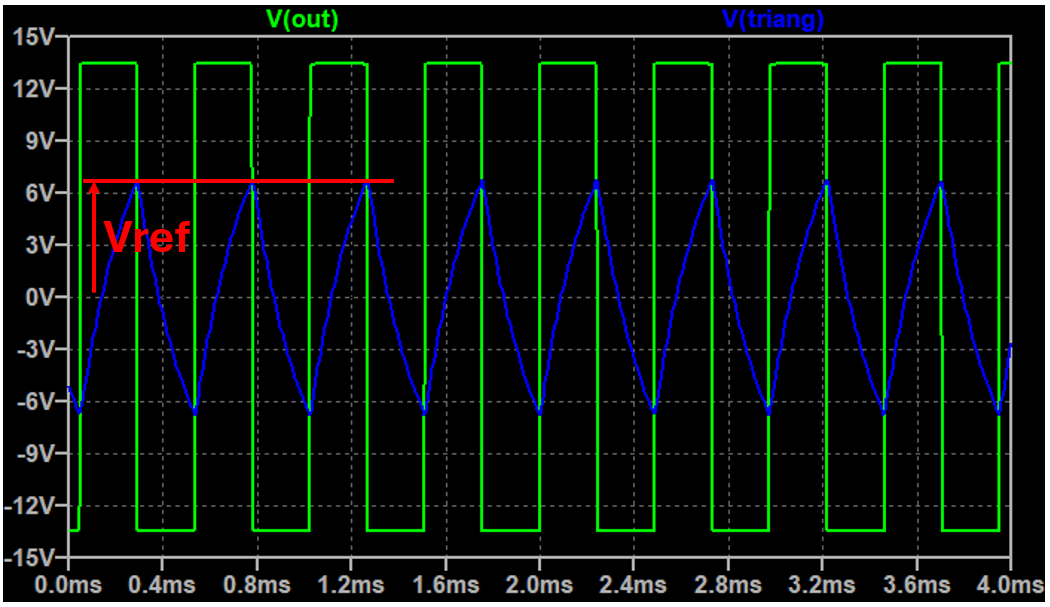

C = 1 *1e-9; %F       % TO BE DECIDED
R1 = 10 *1e3; %ohm    % TO BE DECIDED

% V_ref is the voltage at which the capacitor is clamped in between
V_ref = 7.5; %V       % USUALLY GIVEN/TO BE DECIDED

f = 1 *1e3; %Hz       % USUALLY GIVEN

Vcc = 15; %V

beta = V_ref/Vcc;
R2 = R1/beta-R1;

T = 1/f;

R = T/(2*C*log((1+beta)/(1-beta)));

disp("Astable multivibrator")

Astable multivibrator


disp("R1 = "+ R1)

R1 = 10000


disp("R2 = "+ R2)

R2 = 10000


disp("R3 = "+ R3)

R = 455119.6133


disp("C = "+ C)

C = 1e-09


## Wien Bridge

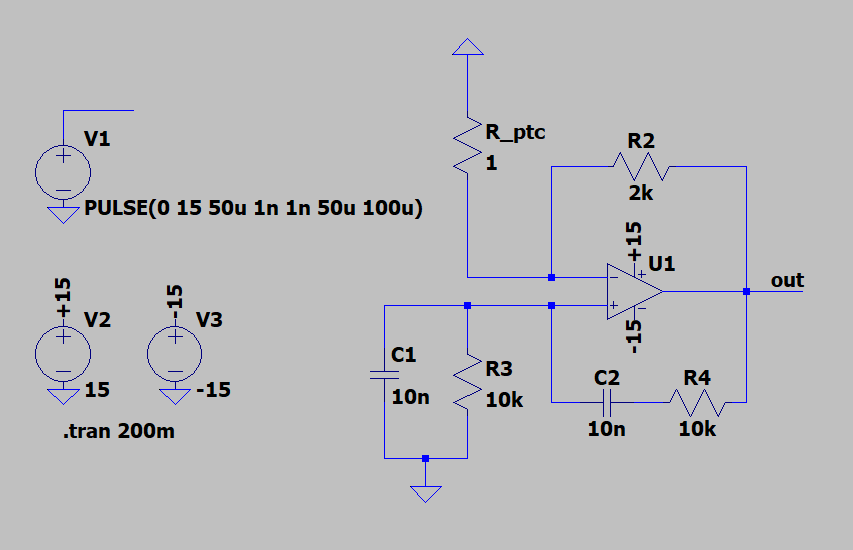

To work it's needed the PTC (positive temperature coefficient - a resistor regulated by the temperature) to implement a control system (AGC: Automatic Gain Control) that regulate the gain of the circuit. A NTC can be applied, just inserted instead of R2. If you don't have PTC/NTC, you can use the next architecture (bang bang) with diode.

R_ptc = 1 *1e3;  %ohm   % TO BE DECIDED
C = 1 *1e-9;     %F     % TO BE DECIDED

f = 1 *1e3;      %Hz    % USUALLY GIVEN

R2 = R_ptc*2;
R = 1/(2*pi*f*C);

disp("Wien Bridge")

Wien Bridge


disp("R_ptc = "+ R_ptc)

R_ptc = 1000


disp("R2 = "+ R2)

R2 = 2000


disp("R (R3 = R4) = "+ R)

R (R3 = R4) = 159154.9431


disp("C (C1 = C2) = "+ C)

C (C1 = C2) = 1e-09


## BANG BANG

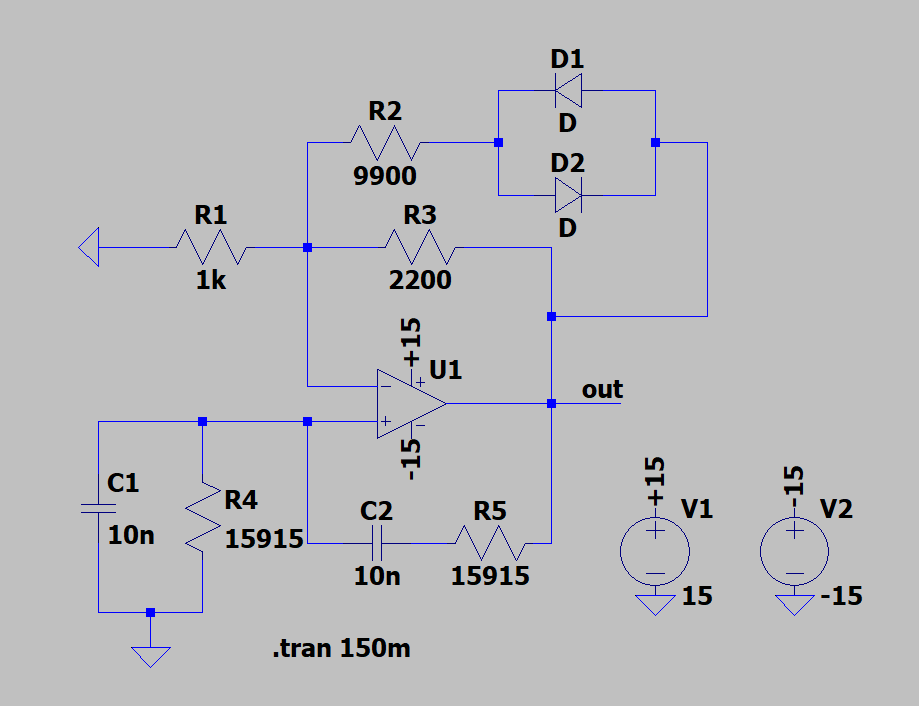


$$V_{out}<< (decreasing) \rightarrow G_1=1+\frac{R_3}{R_1}$$



$$V_{out}>> (increasing) \rightarrow G_2=1+\frac{R_3//R2}{R_1}$$


G1 and G2 are chossen to be G1 > 3 and G2 < 3.

R1 = 1 *1e3; %ohm    % TO BE DECIDED
C = 10 *1e-9; %F     % TO BE DECIDED

G1 = 3.2; % >3       % TO BE DECIDED
G2 = 2.8; % <3       % TO BE DECIDED

f = 10 *1e3; %Hz     % USUALLY GIVEN

R3 = R1*(G1-1);
R2 = R1*(R3-G2*R3)/(R1*(G2-1)-R3);
R = 1/(2*pi*f*C);

disp("Bang Bang")

Bang Bang


disp("R1 = "+ R1)

R1 = 1000


disp("R2 = "+ R2)

R2 = 9900


disp("R3 = "+ R3)

R3 = 2200


disp("R (R4 = R5) = "+ R)

R (R4 = R5) = 1591.5494


disp("C (C1 = C2) = "+ C)

C (C1 = C2) = 1e-08
